**Skills 1 Part 2: David Ramotowski**

Multivariate Data Analysis: Lake data

----------------------------------------------------------------------------------

 --------------------Dealing with files------------------------------------------

----------------------------------------------------------------------------------

Now we are going to analyze a real data set, taken from lake measurements.

First, we must download the data from the course website ICON. 

Use your web browser to download the file and save it in the same directory with this script.

The following shows how we can tell Matlab to go to the directory where the data file is.

Note: set the string below to be the directory where you downloaded

the file 'Lake Data.zip', make sure to include the last '\'. Note, use '/' for

Macs. e.g., '/Users/Desktop/Matlab/'

workdir='/MATLAB Drive/Skills_1_part2/';
cd(workdir);

Now we uncompress the data directory ...

zipdir='Lake Data';
unzip([zipdir,'.zip']);

Note: in Matlab, a string is just an array of characters. So we can  concatenate strings just like we do numeric arrays.

This is the directory where the actual data files reside ...

datdir=[workdir,zipdir];

Here we tell Matlab to go to the directory where the data is

cd(datdir);

This lists all the files in the directory

dir

.                         IceLake_CompleteData.xls  RobustFit2D.m             ice lake.pdf              indy_chemistry.xls        medicine summary.pdf      
..                        LkIndep_CompleteData.xls  csvdesc.pdf               independence lake.pdf     indymanual.xls            
Hist2D.m                  MedLake_CompleteData.xls  ice lake summary.pdf      independence summary.pdf  medicine lake.pdf         



If we only want the data files, we can use

dir *Data.xls

IceLake_CompleteData.xls  LkIndep_CompleteData.xls  MedLake_CompleteData.xls  



This allows us to store the results of our directory query

files=dir('*Data.xls')

files = 3×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


This gives us a structure array. Each element in the array  corresponds to a single file, and has several fields which give information about that file.

To see the file names, we can type

files.name

ans = 'IceLake_CompleteData.xls'

ans = 'LkIndep_CompleteData.xls'

ans = 'MedLake_CompleteData.xls'

To see the size of the files in MB, we can type

[files(:).bytes]/1e6

ans =     6.3642    3.3526    2.8104


The length of the files array tells us the number of data files

Nfiles=length(files)

Nfiles = 3

----------------------------------------------------------------------------------

 --------------------Importing Excel files---------------------------------------

----------------------------------------------------------------------------------

Now we will analyze the data from the first file

fname=files(1).name

fname = 'IceLake_CompleteData.xls'

The 'xlsinfo' command tells us two things:

   status' will tell us if fname is a valid Excel file

  'sheets' will tell us the names of the worksheets in fname

[status,sheets]=xlsfinfo(fname)

status = 'Microsoft Excel Spreadsheet'

sheets = 1×1 cell array
    {'IceLake_CompleteData'}


note that this is a valid file, and it has only one worksheet

New approach using readtable command

Tdata=readtable(fname,'TreatAsMissing',{'.','NA'});
disp(Tdata(1:6,:))

       Site              DateTime          Depth    Temp    pH     EC25    DO     DOSat    Turb
    ___________    ____________________    _____    ____    ___    ____    ___    _____    ____

    {0×0 char }                     NaT     NaN     NaN     NaN    NaN     NaN     NaN     NaN 
    {'IceLake'}    28-Jan-1998 12:00:00       0       0     NaN    NaN     NaN     NaN     NaN 
    {'IceLake'}    28-Jan-1998 12:03:00       1     1.7     7.4    117     8.8    66.4     2.7 
    {'IceLake'}    28-Jan-1998 12:06:00       2     3.3     7.3    116     8.9    70.1     NaN 
    {'IceLake'}    28-Jan-1998 12:09:00       3     2.8     7.3    115     8.8    68.2     NaN 
    {'IceLake'}    28

summary(Tdata)

Variables:

    Site: 59666×1 cell array of character vectors

    DateTime: 59666×1 datetime

        Values:

            Min             28-Jan-1998 12:00:00  
            Median          08-Aug-2000 18:11:49  
            Max             12-Sep-2004 06:06:42  
            NumMissing      1                     

    Depth: 59666×1 double

        Values:

            Min             0     
            Median          6.8   
            Max             15    
            NumMissing      1     

    Temp: 59666×1 double

        Values:

            Min             0     
            Median          7.8   
            Max             28.1  
            NumMissing      2     

    pH: 59666×1 double

        Values:

            Min             6.1   
            Median          7.5   
            Max             9.3   
            NumMissing      3069  

    EC25: 59666×1 double

    

headers = Tdata.Properties.VariableNames;
Tdata_C = table2cell(Tdata);                                    % Convert To Cell Array
NumIdx = cellfun(@isnumeric,Tdata_C);                           % Determine Numeric Values
Vrbls = headers(NumIdx(1,:));                                   % Get Corresponding Headers (If Needed Later)
NrsC = reshape(Tdata_C(NumIdx), size(Tdata_C,1), []);           % Reshape Vector To Matrix
numeric_data = cell2mat(NrsC);                                           % Numeric Array (Finally)

This command will tell us the number of data records, and the (maximum) number of variables measured in each record

[Ndat,Nvar]=size(numeric_data)

Ndat = 59666

Nvar = 7

Note that this is a lot of data points! By the end of this  exercise you will have an idea of the power of Matlab for dealing with large data sets like this.

For later use, we now extract the variable names from the text data (here we exclude the 'site label' and 'date' fields

% i.e the first and second columns).

names=Vrbls;

Now we can extract the DateTime from the text data. Here we convert the dates to a numeric form: the number of (decimal) days since 0/0/0000 0:00

DateVector = table2array(Tdata(:,"DateTime"));
DateTime = datenum(DateVector);

Now we can use 'datestr' to confirm that the dates were imported correctly

datestr(DateTime(2:6))

ans = 5×20 char array
    '28-Jan-1998 12:00:00'
    '28-Jan-1998 12:03:00'
    '28-Jan-1998 12:06:00'
    '28-Jan-1998 12:09:00'
    '28-Jan-1998 12:12:00'


for convenience, we will call the matrix numeric_data simply 'data' 

data=numeric_data;

Lets take a look at the data

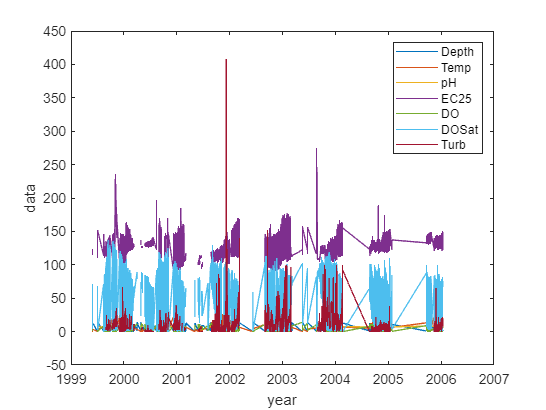

plot(DateTime/365,data);
xlabel('year'); ylabel('data'); legend(names);

This plot is a bit crowded, so lets take a look at the variables seperately

We can use subplots to make a nice figure, but first we need to know how many subplots to use...

plot_cols=ceil(Nvar/2);

now we can plot the data (see 'help subplot')

for var=1:Nvar
    subplot(2,plot_cols,var);
    plot(DateTime/365,data(:,var));
    xlabel('year'); ylabel(names(var));
    title([strtok(fname,'_'),': ',char(names(var)),' Measurements']);
    axis tight;
end

note that strings in Matlab are just arrays of characters, so we can concatenate strings in the same way as arrays. To make our title we concatenated several strings, with some processing (e.g. to remove the file extension from fname). This gives an idea of Matlab's capabilities, but you don't need to understand all this right now.

----------------------------------------------------------------------------------

 --------------------Excluding incomplete records--------------------------------

----------------------------------------------------------------------------------

On inspection, one fact becomes obvious: there are significant gaps in many of the measurements. For example, many pH measurements are missing. When processing data, we can treat gaps (NaN) in  different ways. The simplest is to simply not consider days with missing measurements. We can use logical filtering to find and remove NaN values from  the data as follows

[rnan,cnan]=find(isnan(data));

This finds every entry of 'data' which is NaN, and for each NaN entry it returns a row index (rnan) and a column index (cnan).

The number of missing data points is

Nnan=length(rnan)

Nnan = 13344

Compared to the total number of data points this is  only a small fraction, i.e.

Nnan/prod(size(data))

ans = 0.0319

Here it is about 3% of the data.

The row index for every missing measurement is in 'rnan'.

For a record 'r' which is missing several measurements,  the row index 'r' will be present several times in 'rnan'.

To get a single row index for each incomplete record, we want to ignore repeated values in rnan, i.e. we want

rinc=unique(rnan);

The total number of incomplete records is a still smaller fraction of the total number of records, i.e.

length(rinc)/prod(size(data))

ans = 0.0219

So about 2% of the records have missing data.

The records in the full data set can be indexed by

r0=1:Ndat;

We want an index for only the records which have no missing values, so we let

r=setdiff(r0,rinc);

Now we extract the valid measurements, using this new index

DateTime=DateTime(r);
data=data(r,:);

And we must reset the number of records as well

Ndat=length(data);

----------------------------------------------------------------------------------

 ---------------------------------Basic Statistics-------------------------------

----------------------------------------------------------------------------------

Basic statistics of the data can be computed by using the matrix forms of the statistics functions. Remember that each column of 'data' is a single variable, i.e.

names

names = 1×7 cell array
    {'Depth'}    {'Temp'}    {'pH'}    {'EC25'}    {'DO'}    {'DOSat'}    {'Turb'}


To compute the means and standard deviations of the variables we can use 

dat_avg=mean(data)

dat_avg =     6.6826   10.4142    7.4832  123.2148    5.2749   50.8603    7.9464


dat_dev=std(data)

dat_dev =     3.5688    6.2160    0.5833   16.2922    3.7319   37.1341   10.9165


Lets look at histograms of the data ...

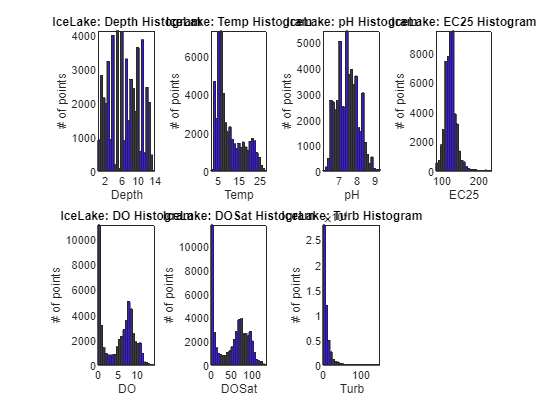

Nbin=25;
for var=1:Nvar
    subplot(2,plot_cols,var);
    hist(data(:,var),Nbin);
    xlabel(names(var)); ylabel('# of points');
    title([strtok(fname,'_'),': ',char(names(var)),' Histogram']);
    axis tight;
end

----------------------------------------------------------------------------------

 --------------------------Multivariate Statistics-------------------------------

----------------------------------------------------------------------------------

We can get an idea of the range and distribution of each variable by using univiariate statistics.

But we can also look at relationships between the variables by using multivariate statistics.

Here we will focus on bivariate statistics: looking at pair-wise relationships between variables. 

A simple statistic which can be used to characterize the relationship between two variables is the correlation coefficient. In Matlab we can compute correlation coefficients between each pair of variables in the data set with

C=corrcoef(data)

C =     1.0000   -0.7116   -0.6633    0.5120   -0.6903   -0.7748    0.1369
   -0.7116    1.0000    0.5499   -0.4073    0.3738    0.5813   -0.0051
   -0.6633    0.5499    1.0000   -0.2295    0.6766    0.7316   -0.1782
    0.5120   -0.4073   -0.2295    1.0000   -0.5061   -0.5406    0.0938
   -0.6903    0.3738    0.6766   -0.5061    1.0000    0.9685   -0.2044
   -0.7748    0.5813    0.7316   -0.5406    0.9685    1.0000   -0.1737
    0.1369   -0.0051   -0.1782    0.0938   -0.2044   -0.1737    1.0000


C is the correlation matrix of the data set. The symmetric matrix C has Nvar rows and columns, and C(i,j)=C(j,i)=correlation between variable i and variable j. 

We can view the correlation matrix using the 'imagesc' command

clf; % first clear the figure to prepare for a new plot
imagesc(C); colorbar; title('Correlation Matrix');

The default axes aspect ratio in Matlab gives us a distorted image,  we can correct this by setting the data aspect ratio to be one-to-one

daspect([1,1,1]); % see 'help daspect'

The axes are labeled by the row and column indices by default. We can change these to give the variable names by using

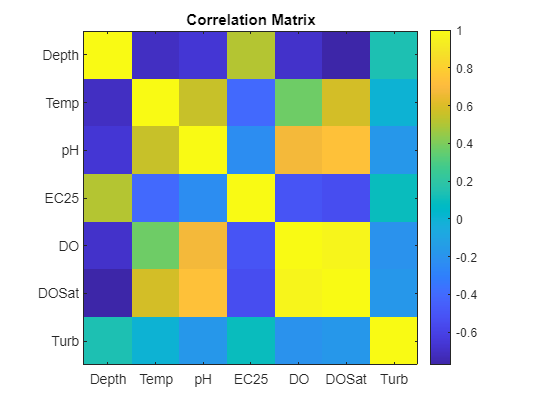

set(gca,'XtickLabel',names,'YtickLabel',names);

Note that 'gca' stands for 'get current axes', and is a 'handle' to the current axes. In Matlab, a handle is a way to refer to a particular graphics object, such as a figure, axes, surface, scatter plot, etc.

Matlab 'handle graphics' allows you to adjust many properties of figures. This is fairly complicated though so we won't go into details here. But these example should give you an idea of what is possible.

We can show the actual values of the correlation matrix as follows...

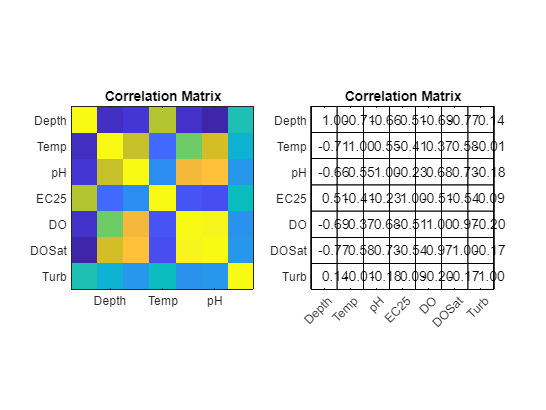

subplot(1,2,1);
imagesc(C); axis equal; axis tight;
set(gca,'XtickLabel',names,'YtickLabel',names);
title('Correlation Matrix');
subplot(1,2,2);
[J,I]=meshgrid((0:Nvar)+0.5);
plot([J,J'],[I,I'],'k-'); axis equal; axis tight;
set(gca,'Xtick',1:Nvar,'XtickLabel',names);
set(gca,'Ytick',1:Nvar,'YtickLabel',names);
title('Correlation Matrix');
[J,I]=meshgrid(1:Nvar);
text(J(:)-0.25,I(:),num2str(C(:),'%2.2f'));
set(gca,'Ydir','reverse');

----------------------------------------------------------------------------------

--------------------------Bivariate Statistics----------------------------------

----------------------------------------------------------------------------------

The correlation matrix indicates that there are some significant relationships  between the different variables in the data set. We now explore some of these relationships.

First we extract the individual variables from the data matrix columns

Depth=data(:,1);
Temp=data(:,2);
pH=data(:,3);
EC25=data(:,4);
DO=data(:,5);
DOSat=data(:,6);
Turb=data(:,7);

Temperature and Depth have a significant correlation (-0.71), so  lets explore this relationship.

The first thing to do is to look at a 2D scatterplot of depth vs temperature

clf; % clear the figure to prepare for a new plot
pts=plot(Depth,Temp,'.'); % here we store a 'handle' to the scatterplot points
xlabel('Depth'); ylabel('Temperature');

This plot is a bit crowded, with points overlapping each other.

We can clean up the plot by making the points smaller, i.e.

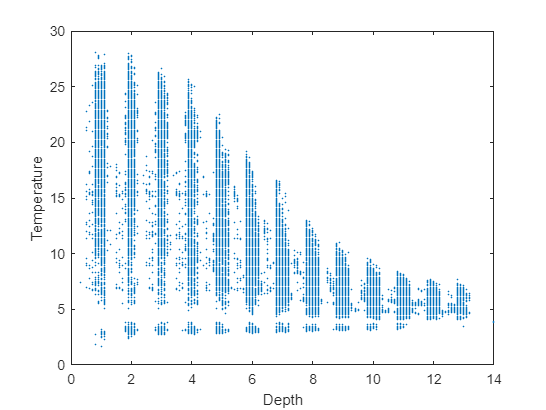

set(pts,'MarkerSize',1);

When we look at this plot, it is hard to see a strong negative correlation. There appears to be a negative relationship between the depth and the maximum  temperature at a given depth. But there are many lower temperatures as well for any depth.  One thing which should strike you when looking at the scatterplot is a 'grid-like' appearance. This is a common occurence in scatterplots, and  can be explained as follows:

The data were measured with a fairly low precision of only one decimal point.  This means that many of the data points are actually repeated. This can be seen if we compare the number of unique data values (for Temperature or Depth)  to the total number of data points

length(unique(Depth))/Ndat

ans = 0.0025

length(unique(Temp))/Ndat

ans = 0.0051

the unique number of (Depth,Temp) pairs is larger, but still relatively small

length(unique([Depth,Temp],'rows'))/Ndat

ans = 0.1347

In other words, particular values are repeated many times in each variable, which leads to overlapping points in the scatter plot.  This means that the scatterplot is not giving us a very good picture of the point density of our data set. For this reason it is usually a good idea to look at a 2D histogram of the data, in addition to a scatter plot. 

There is no 'hist2' function built into Matlab, but I have made an m-file which

can be used to compute a 2D histogram, as demonstrated below.

NbinDepth=10; NbinTemp=15;
[Npts,DepthBins,TempBins]=Hist2D(Depth,Temp,NbinDepth,NbinTemp);

Note: because the function 'Hist2D' is not standard Matlab, to use it,  you must be in the same directory as the m-file 'Hist2D.m'. I have included a help message for Hist2D, so you can see how to use this function with

help Hist2D

  [N,xbin,ybin] = Hist2D(x,y,nx,ny)
 
  Compute 2D histogram of bivariate data
 
  Inputs:
    x = 1st variable (horizontal axis)
    y = 2nd variable (vertical axis)
    nx = number of bins in x direction
    ny = number of bins in y direction
 
  Outputs:
    N = ny by nx matrix of point counts
    xbin = bin centers for x bins
    ybin = bin centers for y bins



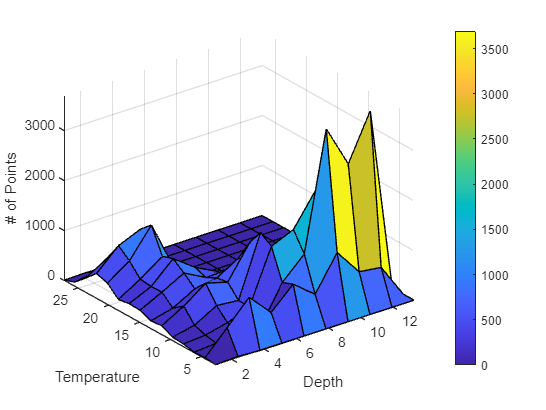

% show the histogram
surf(DepthBins,TempBins,Npts); 
colorbar; axis tight; rotate3d on;
xlabel('Depth'); ylabel('Temperature'); zlabel('# of Points');

Since the histogram counts have a wide range of values, we can see the  pattern more clearly if we increase the contrast of the colormap by coloring the surface with the logarithm of Npts

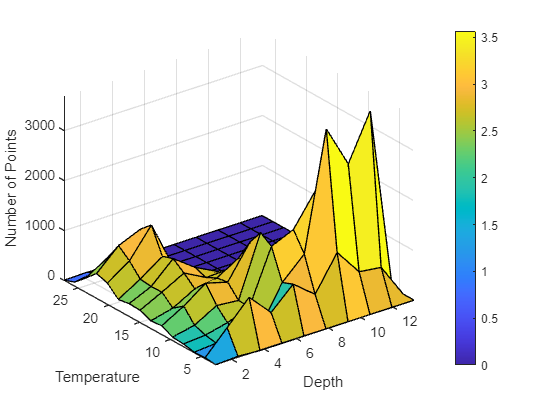

surf(DepthBins,TempBins,Npts,log10(Npts+1)); 
colorbar; axis tight; rotate3d on;
xlabel('Depth'); ylabel('Temperature'); zlabel('Number of Points');

When using 2D point densities to look at relationships between variables it is frequently useful to use a contour plot of the histogram. We can do this with the 'contour' function

Ncont=25;
contour(DepthBins,TempBins,Npts,Ncont); 
colorbar; xlabel('Depth'); ylabel('Temperature');

We can superimpose the data points on the point-density contours

hold on; plot(Depth,Temp,'k.','MarkerSize',1); hold off;

You may note that the point density looks a bit odd: many points seem to plot in regions where Npts is low ... this is because of the low precision of the data, which leads to many overlapping points in the scatter plot. This is a reason why it is good to look at histograms in addition to scatter plots

A common way to analyze 2D data is to fit a regression line.

We can do this using the 'polyfit' command, specifying a degree-1 polynomial, i.e. a line

P=polyfit(Depth,Temp,1);

P has the polynomial coefficients (see 'help polyfit' and 'help polyval')

To draw the line, we first compute the end-points of the line

Dfit=[min(Depth),max(Depth)];
Tfit=polyval(P,Dfit); % Note: since P is a degree-1 polynomial, this gives Tfit=P(1)*Dfit+P(2)

Now we can add the regression line to the plot:

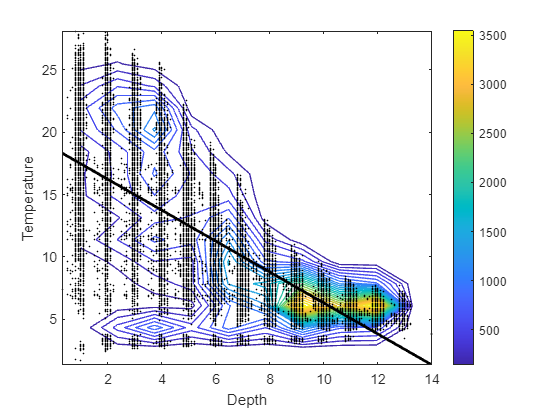

hold on; plot(Dfit,Tfit,'k-','LineWidth',2); hold off;

A simple measure of how good the regression does at predicting Temp is the r^2 value, i.e. the square of the correlation coefficient between Depth and Temp. We already computed r when we computed C. 

Remembering the order of the variables ...

names

names = 1×7 cell array
    {'Depth'}    {'Temp'}    {'pH'}    {'EC25'}    {'DO'}    {'DOSat'}    {'Turb'}


% We see that r=C(1,2)=C(2,1)=
r=C(1,2)

r = -0.7116

% And so r^2 =
r^2

ans = 0.5064

This means that we can explain about 51% of the variation in Temperature by using Depth in a linear regression.

The following requires the Statistics Toolbox (comment out if you need)

The Statistics Toolbox allows you to get statistics (e.g. the 'F'-value) for a regression by using the 'regress' command (see 'help regress'). However the regress command is much more than a least-squares line-fitting routine. 

The regress command solves a generalized linear least-squares problem of the form

                   y=X*b

where y is a vector of observed variables, X is a MATRIX of predictor variables, and b is a vector of coefficients which are to be fitted. Generalized linear least-squares is a very general method, and the 'regress' function can be used to fit lines, general polynomials, best-fit planes or hyperplanes, and many other 'linear models'. To understand the meaning of y=X*b requires some knowledge of linear algebra, which is beyond the scope of this course. However as an example we will use 'regress' to  fit a line to the Temperature/Depth data. To fit a line 'Temp=a*Depth+c', we represent the value 'Temp' using a dot-product:

       Temp = X*b = [Depth,1]*[a;c]

% where Temp, Depth, and '1' are vectors. We construct the 'X' matrix by

X=[Depth,ones(Ndat,1)];

Now we specify an 'alpha' value, used to compute (1-alpha)*100% confidence

alpha=5e-2; % i.e 5%

intervals on the fitted coefficients and on the residuals of the fit

[b,b_bounds,res,res_bounds,stats]=regress(Temp,X,alpha);

Notice that b is the same as P

P

P =    -1.2394   18.6965


b'

ans =    -1.2394   18.6965


But now we have bounds on the coefficients

b_bounds

b_bounds =    -1.2501   -1.2287
   18.6157   18.7774


and we also have summary statistics for the regression

rsqr_fit=stats(1)

rsqr_fit = 0.5064

F_fit=stats(2)

F_fit = 5.1816e+04

p_fit=stats(3)

p_fit = 0

Note that the r^2 value is the same as we computed before. It is a property of linear least squares that the mean residual  is zero, i.e.

mean(res)

ans = 8.7191e-14

this is essentially zero when compared to 'eps' 

A better check is to look at the statistical distribution of  residuals from the fit 

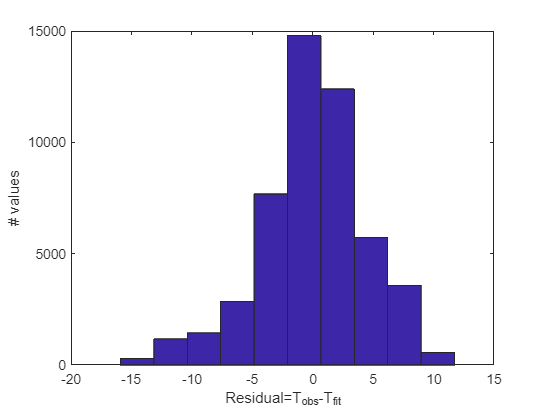

hist(res); xlabel('Residual=T_{obs}-T_{fit}'); ylabel('# values');

We can see that this distribution is negatively skewed (i.e. skewed to the left), which suggests a bad fit

skewness(res)

ans = -0.4378

Note that the statistics calculated by the 'regress' function assumed that the 'errors' in our measurements were normally distributed, i.e. symmetric.

If we look at the distribution of residuals over depth, we can see that there is a systematic error at low depths

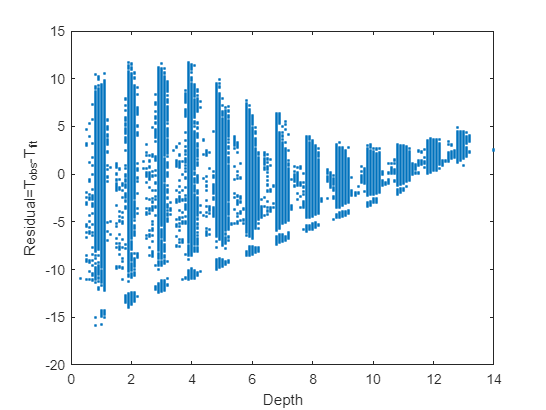

plot(Depth,res,'.'); xlabel('Depth'); ylabel('Residual=T_{obs}-T_{fit}');

Our 2D histogram plot showed us that while there is some relationship between Temperature and Depth, this relationship

is NOT well represented by a line. 

contour(DepthBins,TempBins,Npts,Ncont); colorbar; 
hold on; plot(Depth,Temp,'k.',Dfit,Tfit,'k-','MarkerSize',1,'LineWidth',2); hold off;
xlabel('Depth'); ylabel('Temperature');

Hence it is not surprising that our linear regression produced a bad fit.

Let's try something different

Since we have so much data, instead of assuming a linear relationship, we can just let the data 'tell us' what relationship is appropriate. One way to do this is to bin the 'x' data (i.e. Depth), and then let our empirical prediction of 'y' (i.e. Temp) be the average value of 'y' within each 'x' bin. Here we use the median value, which is more robust to outliers than a simple mean. 

I have implemented this procedure in an m-file, RobustFit2D

Note: because the function 'RobustFit2D' is not standard Matlab, to use it, you must be in the same directory as the m-file 'RobustFit2D.m'. 

Nbin_fit=15;
[Depth_fit,Temp_fit]=RobustFit2D(Depth,Temp,Nbin_fit);

I have included a help message for RobustFit2D, so you can see how to use this function with

help RobustFit2D

We can compare this empirical curve to the linear fit

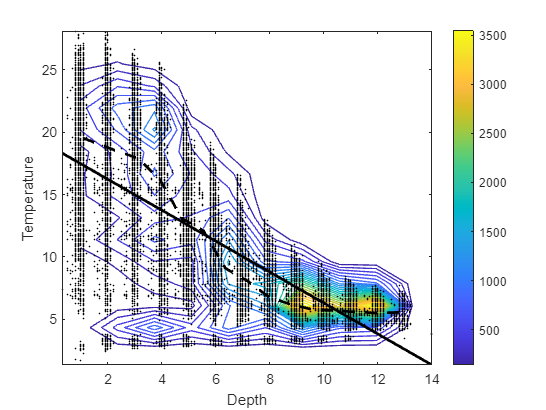

hold on; plot(Depth_fit,Temp_fit,'k--','LineWidth',2); hold off;

The empirical curve captures the relationship much more effectively.  We might do even better if we predict Temp using bin-statistics other than an average, for instance the mode, but I will leave this as an exercise for those who are interested.

On a final note, you might be thinking: for a line, Temp=a*Depth+c, I can easilly compute Temp for any Depth, but the empirical Temp curve is only defined at Depth_fit. This is true, but we can easilly extend our Temp predictions to any Depth by using interpolation. As an example, we can predict Temp at each measured Depth with:

Depth2=unique(Depth);
Temp2=interp1(Depth_fit,Temp_fit,Depth2,'pchip');

The function interp1 interpolates in 1D ( i.e. f(x) , but not f(x,y) ), see 'help interp1'

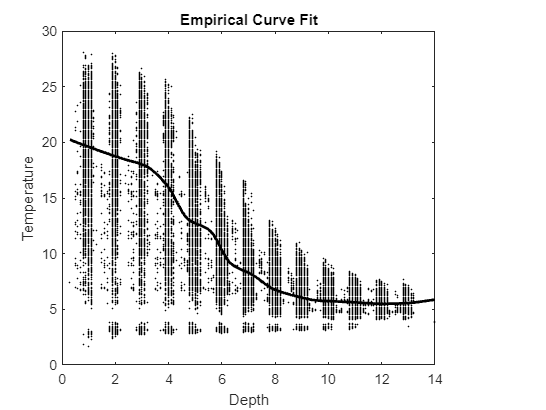

plot(Depth,Temp,'k.',Depth2,Temp2,'k-','LineWidth',2,'MarkerSize',1);
xlabel('Depth'); ylabel('Temperature');
title('Empirical Curve Fit');

Sometimes it is easier to view depth profiles of variables by switching the axes.

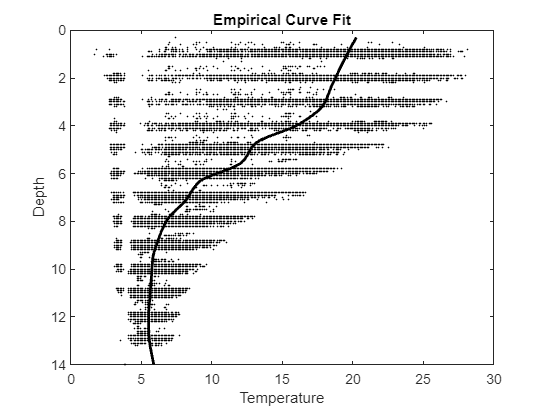

plot(Temp, Depth,'k.',Temp2, Depth2,'k-','LineWidth',2,'MarkerSize',1);
xlabel('Temperature'); ylabel('Depth');
title('Empirical Curve Fit');
set(gca,'YDir','reverse')